# Normalizing Electricity Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

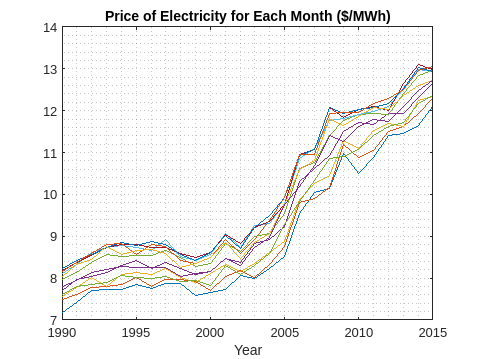

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = com + res + ind;
price = price * 1000 / 100;
revenue = price .* usage;

load ../data/electricity.mat
plot(1990:2015, price')
grid minor
title("Price of Electricity for Each Month ($/MWh)")
xlabel("Year")

## Task 1

price2015 = price .* dollar2015;

This code creates a vector with the number of days in each month.

numDaysInMonth = [31 mean([28 28 28 29]) 31 30 31 30 31 31 30 31 30 31]'

numDaysInMonth =    31.0000
   28.2500
   31.0000
   30.0000
   31.0000
   30.0000
   31.0000
   31.0000
   30.0000
   31.0000


## Task 2

avgDailyUsage = usage ./ numDaysInMonth

avgDailyUsage = 1.0e+09 *

    3.0781    3.0276    2.9507    3.0256    3.3492    3.1146    3.5036    3.4247    3.3080    3.5871    3.5358    4.0989    3.7707    4.0088    4.1007    4.0415    3.8845    4.0415    4.3022    4.3945    4.7581    4.6794    4.0607    4.2511    4.7262    4.4365
    2.6371    2.8122    2.9085    2.9531    3.1746    3.0683    3.4024    3.1952    3.0639    3.0677    3.4889    3.5355    3.4192    3.9270    3.9810    3.7758    3.6995    4.2996    4.1966    4.0783    4.3483    4.2517    3.8221    4.0040    4.5478    4.3815
    2.3194    2.3827    2.3792    2.6792    2.5769    2.5634    2.8076    2.6267    2.7730    2.8846    2.7298    2.9937    3.0748    3.2117    3.1918    3.3569    3.3857    3.4095    3.4569    3.4355    3.6061    3.3846    3.2052    3.6160    3.6849    3.7699
    2.1730    2.1963    2.2817    2.3234    2.3164    2.2861    2.4872    2.4249    2.4715    2.5754    2.5399    2.7485    2.8469    2.7816    2.8459    2.8916    2.9791    3.0094    3.0722